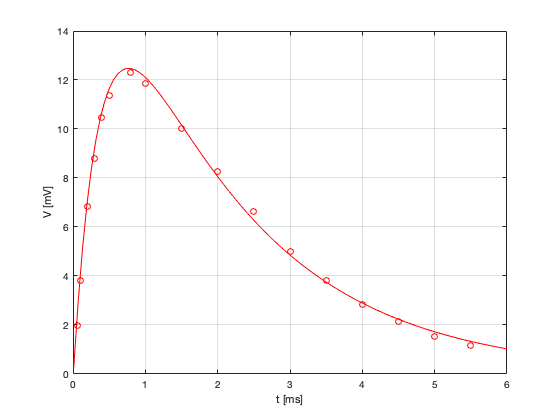

addpath("routine/");clear;figure
R=1e5;
C=1e-8;
R_osc = 0.5e6; C_osc = 16e-12 + 104e-12;
tau=R*C;
e = exp(1);

%%risposta impulsionale impulso di 5V a 100 Hz e 10 us per tempi <<tau:  in 1 ms arriva a 36 mV, variando width cambia
%%massimo ma resta sempre a tau. con impulso più largo la magia finisce
f=50; A=5;
offset=2.5; width=10e-6;
t0 = 10e-6;
t_1 = linspace(t0, 6e-3);

%dati doppio amp
t1=1e-6*[90    200   350   500   700 1e3   1.5e3 2e3 2.5e3 3e3  3.5e3  4e3  4.5e3 5.5e3 ];%7.6e3
V1=1e-3*[3.125 7.250 11.57 14.87 17  18.2  16.2  13  9.6   6.8  4.6    3.1  1.7   .450  ];%-.4
%dati senza amp
t3=1e-6*[60 100 200  300 400   500   790   1e3   1.5e3 2e3  2.5e3 3e3 3.5e3 4e3 4.5e3 5e3  5.5e3 ];%16.2e3
V3=1e-3*[2  3.8 6.85 8.8 10.45 11.35 12.30 11.85 10    8.25 6.65  5   3.8   2.85  2.15  1.55 1.15];%-.75
%dati singolo amp
t2=1e-6*[940];%16.2e3
V2=1e-3*[16.83];%-.75

%doppio amp
syms s t
G_(s) = (1/(1+s*tau)^2)*(1/s - exp(-s*t0)/s)*A;
G(t) = ilaplace(G_);

%plot(t_1*1e3, G(t_1)*1e3, "Color",'blue');hold on
%scatter(t1*1e3,V1*1e3,'blue')

%zero amp
syms s t Z Zeq
Z = R_osc/(1+s*R_osc*(C+C_osc));
Zeq = R/(1+s*tau);
G_(s) = (Zeq/R) * Z/(Zeq+R+Z) *A*(1-exp(-s*t0))/s;

%G_(s) = (1/((R/R_osc) * (2+s*tau) * (1+s*R_osc*(C+C_osc)) +1)) *A*(1-exp(-s*t0))/s;
%G_(s) = (1/s - exp(-s*t0)/s)*A* (1/((s-a)*(s-b)))*1e6;
G(t) = ilaplace(G_);
plot(t_1*1e3, G(t_1)*1e3,"Color",'red');hold on
scatter(t3*1e3,V3*1e3,'red')


%singolo amp
syms s t Z
Z = R_osc/(1+s*R_osc*(C+C_osc));
G_(s) = (1/(1+s*tau))*(Z/(Z+R))*(1/s - exp(-s*t0)/s)*A;
G(t) = ilaplace(G_);

%plot(t_1*1e3, G(t_1)*1e3,"Color",'green');hold on
%scatter(t2*1e3,V2*1e3,'green')


grid on;
xlabel("t [ms]")
ylabel("V [mV]")

%legend({'Modello doppio op-amp','Dati doppio op-amp','Modello senza op-amp','Dati senza op-amp','Modello singolo op-amp','Dato singolo op-amp'})


%p(s) = s^2 * tau^2 + s*(3*tau + tau*R/R_osc) + 1 + 2*R/R_osc;
%eq = p(s)==0;
%sol = solve(eq,s);
%a = sol(1); b = sol(2);